# Taller 1: Modelo Cinemático de un Carro

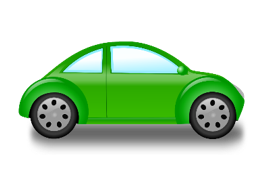

Hasta ahora hicimos un análisis muy detallado del modelo de robot diferencial. Otro tipo de architectura de control de dirección es la de los vehículos o también conocida como "Ackerman Steering" donde las ruedas de atrás tienen un actuador y las delanteras controlan la dirección mediante un timón. 

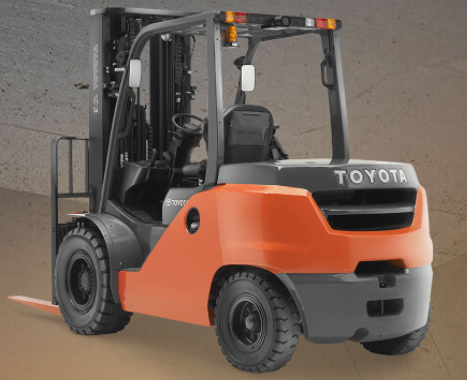

Imagen tomada de [https://www.toyotaforklift.com/](https://www.toyotaforklift.com/)

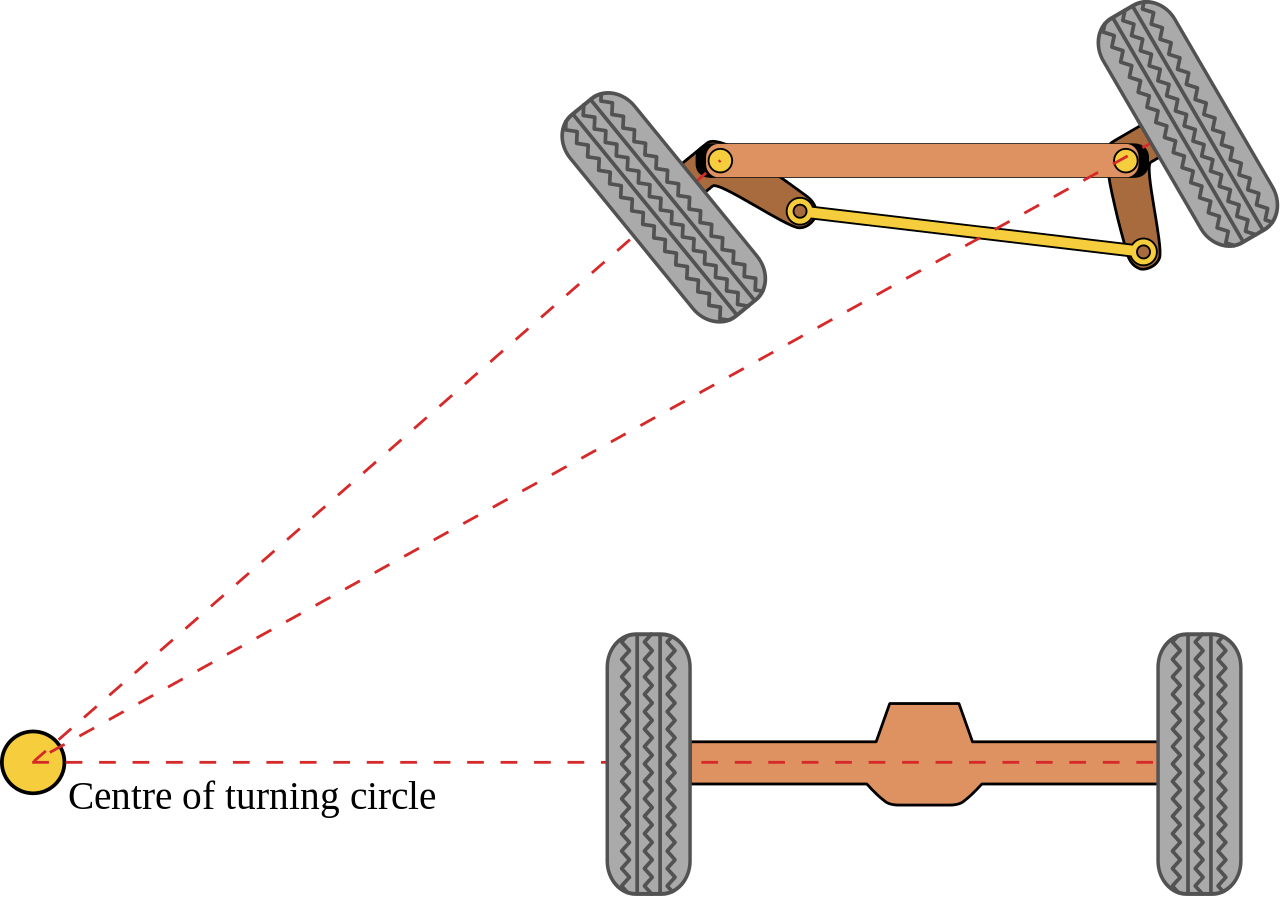

Imagen tomada de:  https://en.wikipedia.org/wiki/Ackermann_steering_geometry#/media/File:Ackermann_turning.svg

## **Bicycle Model**

Aunque también se puede trabajar con el modelo de Ackerman y deducir las ecuaciones, existe una simplificación y es el "Bicycle Model" donde las dos llantas delanteras se proyectan a una sola: 

## 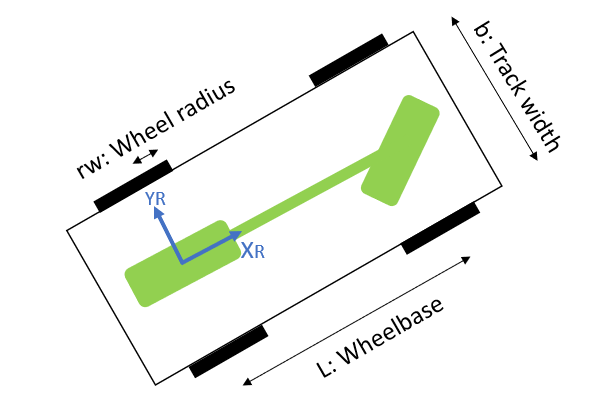

Donde los parámetros geométricos son el *Wheelbase, *el *Track Width, y Wheel Radius*.  También es muy importante notar en el diagrama que pusimos el frame del robot en el eje trasero del robot.  Otras opciones para poner este frame son en el centro de gravedad del modelo o en el eje delantero. Las ecuaciones del modelo dependen donde este frame. Lo más común es ponerlo en el eje trasero y la deducción de las ecuaciones es más simple. 

Como se puede ver en el diagrama a continuación, en este modelo también el robot girara instantáneamente alrededor de un **ICC** con un radio de curvatura **r  **(esto también es evidente si vamos en un carro y dejamos el timón en un ángulo constante)

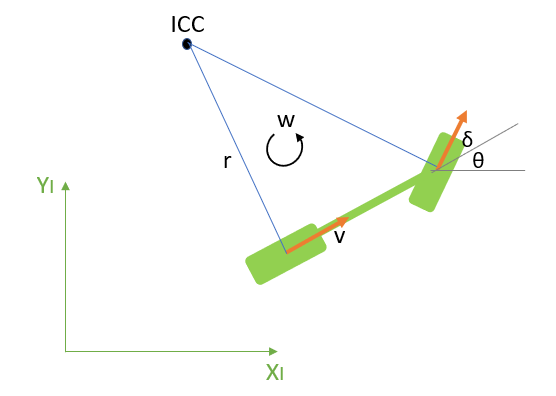

Las entradas del modelo son:

- El parámetro $\delta$ es el ángulo en radianes de la dirección.

- La velocidad lineal de las ruedas traseras  $v_x^r$ . También ya sabemos que también podemos hacer que la entrada sea la velocidad angular de las ruedas con la relación: 

 $v_x^R =w_r \;r_w$    (1.1)

Donde $w_r$es la velocidad angular de la llanta trasera (en este caso la r hace referencia a rear y no a right)

**Pregunta 1:**

Por favor demostrar que el modelo cinemático se puede expresar por las ecuaciones: 

$\begin{array}{l}
{\dot{x} }^I =v_x^R \;\mathrm{cos}\;\theta \\
{\dot{y} }^I =v_x^R \;\mathrm{sin}\;\theta \\
{\theta^˙ }^I =\;\frac{v_x^R \;\mathrm{tan}\left(\delta \right)}{L}
\end{array}$          (1.2) 


$${\xi^˙ }^R =\left\lbrack \begin{array}{c}
{\dot{x} }^R \\
{\dot{y} }^R \\
{\theta^˙ }^R 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\mathrm{cos}\;\theta  & -\mathrm{sin}\;\theta  & \;0\\
\mathrm{sin}\;\theta  & \mathrm{cos}\theta  & \;\;0\\
0 & 0 & \;\;\;\;1\;
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_x^R \\
0\\
w
\end{array}\right\rbrack$$


A través de la matriz de rotación es posible confirmar que las ecuaciones para la velocidad en X y Y son correctas. Sin embargo,

para la velocidad angular se tiene que hallar una nueva expresion.

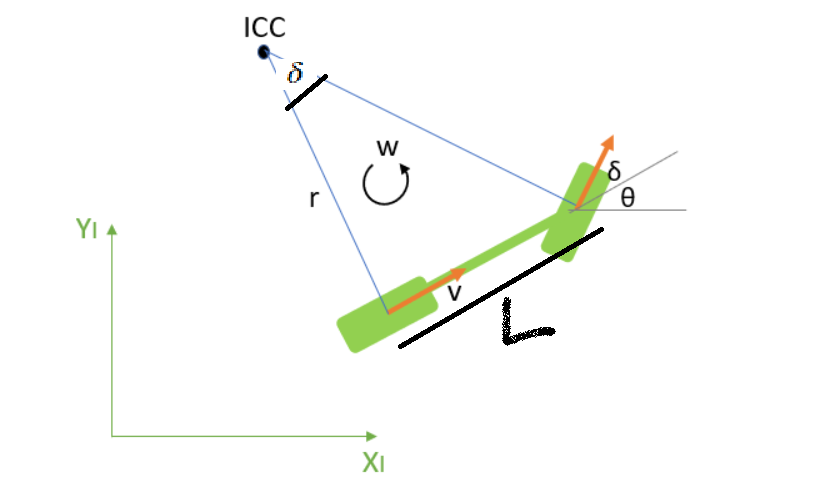

Basandome en el gráfico anterior se puede obtener la expresión de la velocidad ángular:


$$r=\frac{L}{\mathrm{tan}\left(\delta \right)}$$
           
$$w=\frac{v_x^R }{r}$$
              
$$w=\frac{v_x^R \;\mathrm{tan}\left(\delta \right)\;}{L}\;$$
           

**Pregunta 2:**

Por favor comparar esta ecuación con la ecuación  (5.5) de la Clase 2 (lecture_02.mlx) del robot diferencial. Aunque son similares, hay una diferencia clara desde el punto de vista matemático. Esta diferencia como se ve reflejada en la realidad al controlar un carro? 


$$\begin{array}{l}
{\dot{x} }^I =v^R \;\cos \;\theta \\
{\dot{y} }^I =v^R \;\sin \;\theta \\
{\theta^˙ }^I =w^R 
\end{array}$$
                              
$$\begin{array}{l}
{\dot{x} }^I =v_x^R \;\mathrm{cos}\;\theta \\
{\dot{y} }^I =v_x^R \;\mathrm{sin}\;\theta \\
{\theta^˙ }^I =\;\frac{v_x^R \;\mathrm{tan}\left(\delta \right)}{L}
\end{array}$$


La diferencia evidente que tienen estos dos conjuntos de ecuaciones es en la velocidad angular, en donde encontramos que para el modelo de bicicleta se tendrá un relación directamente propocional con respecto al ángulo que tiene el carro con el centro de giro inmediato e inversamente propocional con la longitud de la base. De lo cual podemos concluir que se tendrá un mayor control sobre la velocidad ángular al momento de girar en un carro, ya que esta dependerá del ángulo de giro que le demos al timón. Siendo mucho más seguro el manejo del auto en comparación a una tracción diferencial. 

**Pregunta 3**

Crear una clase en MATLAB llamada *BicycleModel *e implementar los siguientes métodos:

- calcForwardKinematics

- calcInverseKinematics

**Forward Kinematics**

Recordar que en la cinemática inversa se expresa la velocidad 2D en el robot frame en función de las entradas del robot. En el caso del bicycle model, 

$\begin{array}{l}
{\xi^˙ }^R =\left\lbrack \begin{array}{c}
v_x^R \\
v_y^R \\
w_z^R 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\dot{x} }^R \\
{\dot{y} }^R \\
w^R 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{r_w \;w}_r \;\\
0\\
\frac{{r_w \;w}_r \;\tan \left(\delta \right)}{L}
\end{array}\right\rbrack \\
\\
\ 
\end{array}$     (1.3)

**Inverse Kinematics**

Recordar que en la cinemática inversa, se expresa las entradas del robot en función de la velocidad 2D en el robot (body) frame.  En el caso del bicycle model, 

$\begin{array}{l}
w_r =\;\frac{v_x^R }{r_w }\\
\delta =\mathrm{atan}\left(\frac{w_z^R \;\;L}{v_x^R }\right)
\end{array}$        (1.4)

Mostrar con un ejemplo como se usa la clase y cada método implementado. Tener en cuenta el caso cuando $v_x^R$ = 0

%Caso0 se prueba con valores tipicos la clase BicycleModel creada
Wheelradius0=0.5

Wheelradius0 = 0.5000

WheelBase0=1

WheelBase0 = 1

wr0=1

wr0 = 1

delta0=0.01

delta0 = 0.0100

robot1 = BicycleModel(Wheelradius0,WheelBase0)

robot1 =   BicycleModel with properties:

    WheelRadius: 0.5000
      WheelBase: 1


Velocidades = robot1.calcForwardKinematics(wr0,delta0)

Velocidades =     0.5000
         0
    0.0050


[Wr,Delta]= robot1.calcInverseKinematics(Velocidades)

Wr = 1

Delta = 0.0100


%%Caso1, En el caso de Vx=0 el angulo de direccion no es posible de
%%calcular. Ademas wr=0 para que Vx sea igual a 0
Wheelradius1=0.01

Wheelradius1 = 0.0100

WheelBase1=0.3

WheelBase1 = 0.3000

wr=0

wr = 0

delta=0.1

delta = 0.1000

robot2 = BicycleModel(Wheelradius1,WheelBase1)

robot2 =   BicycleModel with properties:

    WheelRadius: 0.0100
      WheelBase: 0.3000


Velocidades_1 = robot1.calcForwardKinematics(wr,delta)

Velocidades_1 =      0
     0
     0


[Wr_1,Delta_1]= robot2.calcInverseKinematics(Velocidades_1)

Wr_1 = 0

Delta_1 = 0

**Pregunta 4: **

Implementar en Simulink un subsistema del modelo bicicleta del carro donde las entradas son 

- velocidad angular de las llantas traseras 

- ángulo del timón 

Al simular el modelo se deben ver la trajectoria en el espacio del robot. 

open('BicycleModel_implementation.slx');

**Pregunta 5:**

Según lo que han visto en este taller,  la tracción diferencial parece más fácil que controlar que la tracción del carro. Si es por eso, por qué los carros que vemos en la calle no tienen tracción diferencial y la tracción diferencial solo la vemos en robots?

La construcción y manejo de un carro con tracción diferencial sería muy complicado, ya que para la conducción se tendría que manejar las velocidades diferentes de cuatro ruedas al mismo tiempo. Y, en general para la construcción de un carro sería mucho más simple como se realiza hoy en día, debido a que, la interconexión de la dirección de las cuatros ruedas y el encontrar una manera sencilla de manejar estas sería muy complejo.

**Nota:** Tal vez uno de los pocos ejemplos de carros con tracción diferente es el RoboMovil del Centro Aerospacial Alemán DLR. No es tracción diferencial pero es otro concepto:

[https://www.youtube.com/watch?v=CfSGFrbRlzc](https://www.youtube.com/watch?v=CfSGFrbRlzc)